load('C:\Users\Asus\Desktop\data_A')

    x=data_noise(1:1000,1:11);
    y=data_noise(1:1000,12);
    rng('default');
    cv = cvpartition(size(x,1),'HoldOut',0.3);
    idx = cv.test;
% Separate to training and test data
   x_train = x(~idx,:);
   x_test  = x(idx,:);
   y_train = y(~idx,:);
   y_test  = y(idx,:); 

%%first method
S = [];
r = y_train;

max_regressors = 11; 
epsilon = 0.0001; 

while numel(S) < max_regressors
    CC = zeros(size(x_train, 2), 1); 
    
    for i = 1:size(x_train, 2)
        if ~ismember(i, S)
            % Calculate correlation coefficient
            CC(i) = abs(corr(x_train(:, i), r)); 
        end
    end
    % Select regressor 
    [~, idx] = max(CC);
    S = [S idx]; 
    Phi = x_train(:, S);  
    % Calculate coefficient 
    teta = Phi \ y_train;   
    % Calculate residual 
    r = y_train - Phi * teta;    
    % Stop
    if max(CC) < epsilon
        break;
    end
end


selected_regressors = S;
weights = teta;

Phi_test = x_test(:, selected_regressors);
y_pred = Phi_test * weights;

%    y_pred_train=x_train*teta_hat;
%    y_pred=x_test*teta_hat;
   
   MSE = mean((y_pred - y_test).^2);
   MSE_test = MSE;
   
%    MSE1 = mean((y_pred_train - y_train).^2);
%    MSE_train = MSE1;
   
   errors =  y_test - y_pred;
   error_test=errors;
   
%    errors1 =  y_train - y_pred_train;
%    error_train=errors1;
   
   MAE = mean(abs(y_pred - y_test));
   MAE_test = MAE;

%    MAE1 = mean((y_pred_train - y_train).^2);
%    MAE_train = MAE1;
   
   
% subplot_rows = 3;
% subplot_cols = 4;
% 
%     % Generate the plot for the current i
% subplot(subplot_rows, subplot_cols, i);
u = x_test(:, 2);
cov_teta_hat = ((errors' * errors) * (x_train' * x_train)^-1)/(700-8);

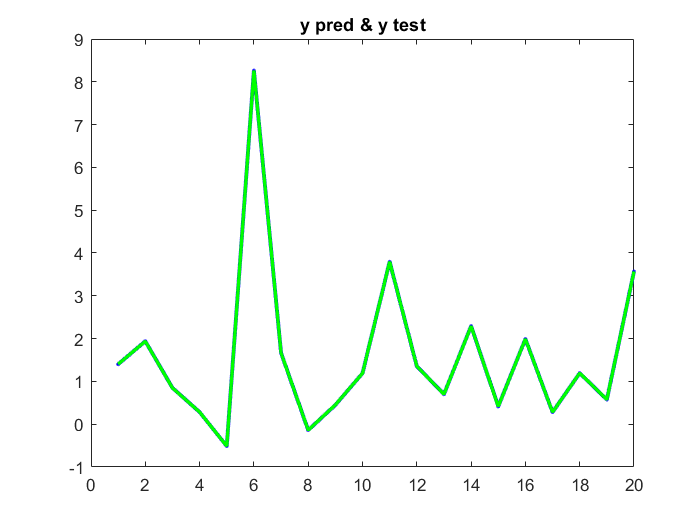

errbar = sqrt(diag(x_test * cov_teta_hat * x_test'));






plot(y_pred(1:20,:),'.-b','linewidth',2.3);
hold on
plot(y_test(1:20,:),'-g','linewidth',2);
title("y pred & y test");
 hold off 

 
%  subplot(subplot_rows, subplot_cols, i);
% plot(y_pred,'.-b','linewidth',2.3);
% hold on
% plot(y_test,'-g','linewidth',2);
% title("y pred & y test");
%  hold off 
%  
 
 
 

ghodrat_noise=errors.'*errors/(700-8);
deghat_takhmin=cov(weights);
deghat_model=MSE;

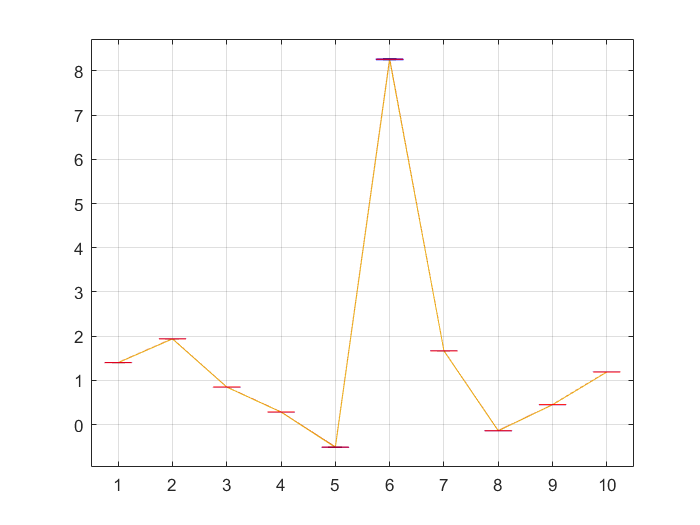

    
u1=1:1:10;
plot((y_pred(1:10,:)),'-');
hold on
plot((y_pred(1:10,:)+errbar(1:10,:)));
hold on
plot((y_pred(1:10,:)-errbar(1:10,:)));
grid

x=sort(u1).';
y=sort(y_pred(1:10,:)).';
data = [((y_pred(1:10,:))-errbar(1:10,:)).'; (y_pred(1:10,:)).'; ((y_pred(1:10,:))+errbar(1:10,:)).'];

% Add a box plot
boxplot(data, 'positions', x, 'widths', 0.5);
hold off

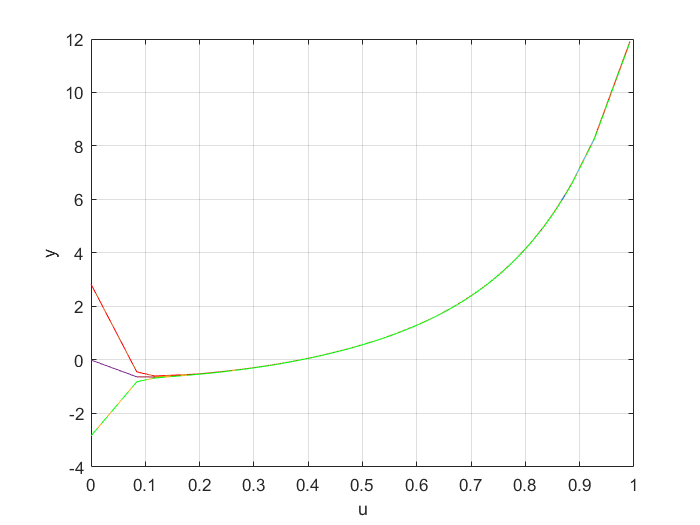

    upper_bound=y_pred + errbar;
    lower_bound=y_pred - errbar;
    
   [a_sorted, sort_idx] = sort(u);
b_sorted = y_pred(sort_idx);
c_sorted =upper_bound(sort_idx);
d_sorted =lower_bound(sort_idx);
% CI_low_sorted=CI_low(sort_idx)
% CI_high_sorted=CI_high(sort_idx)


plot(a_sorted, b_sorted, '-');
hold on;
plot(a_sorted, c_sorted, '-');
hold on
plot(a_sorted, d_sorted, '-');
hold on
% plot(a_sorted, CI_low_sorted, '-');
% hold on
% plot(a_sorted, CI_high_sorted, '-');
% hold on

for j = 1:length(a_sorted)-1
    x = [a_sorted(j), a_sorted(j+1)];
    y = [b_sorted(j), b_sorted(j+1)];
    plot(x, y);
    hold on
    xx = [a_sorted(j), a_sorted(j+1)];
    yy = [c_sorted(j), c_sorted(j+1)];
    plot(xx, yy, 'r--');
     hold on
    xxx = [a_sorted(j), a_sorted(j+1)];
    yyy = [d_sorted(j), d_sorted(j+1)];
    plot(xxx, yyy, 'g--');
%          hold on
%     xxxx = [a_sorted(j), a_sorted(j+1)];
%     yyyy = [CI_low_sorted(j), CI_low_sorted(j+1)];
%     plot(xxxx, yyyy, 'g--');
%          hold on
%     xxxxx = [a_sorted(j), a_sorted(j+1)];
%     yyyyy = [CI_high_sorted(j), CI_high_sorted(j+1)];
%     plot(xxxxx, yyyyy, 'g--');
end
    xlabel('u');
    ylabel('y');


    % Set subplot title

    hold off

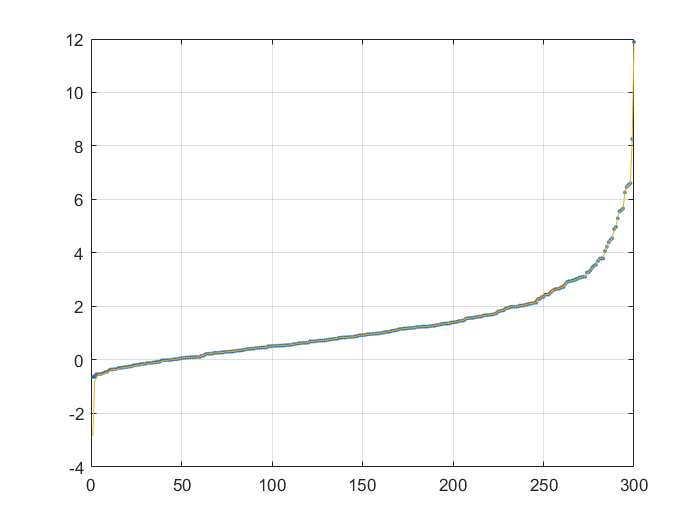

figure;
plot(sort(y_pred),'.');
hold on
plot(sort(y_pred+errbar));
hold on
plot(sort(y_pred-errbar));
grid

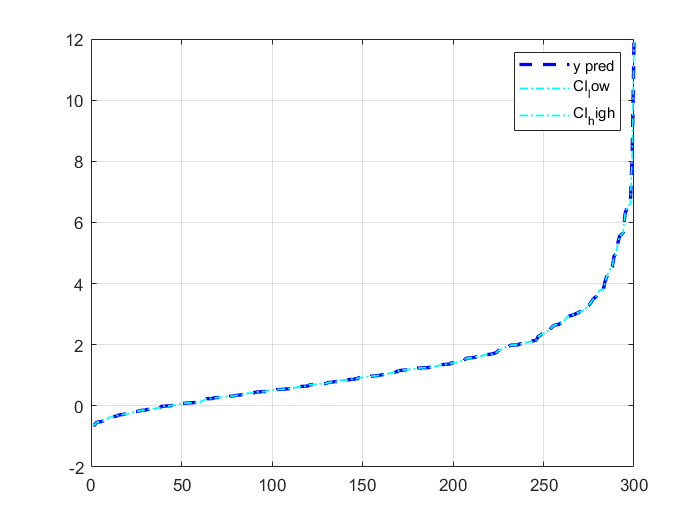

% Calculate the confidence interval
CI = 1.96 * std(errors) / sqrt(length(errors));
CI_low = y_pred - CI;
CI_high = y_pred + CI;

% Plot 
figure
plot(sort(y_pred), '--b', 'LineWidth', 2)
hold on
plot(sort(CI_low), '-.c', 'LineWidth', 1)
hold on
plot(sort(CI_high), '-.c', 'LineWidth', 1)
grid
legend('y pred', 'CI_low', 'CI_high')
hold off

%%second method

max_features = size(x_train, 8);
[selected_features, coefficients] = OLS1(x_train, y_train, max_features);
x_test_selected = x_test(:, selected_features);
y_pred = x_test_selected * coefficients;

mse = mean((y_test - y_pred).^2);
fprintf('Mean Squared Error: %.4f\n', mse);


function [selected_features, coefficients] = OLS1(X_train, Y_train, max_features)
    selected_features = [];
    coefficients = [];
    
    for i = 1:max_features
        residuals = Y_train - X_train(:, selected_features) * coefficients;
        correlations = abs(corr(X_train(:, ~selected_features), residuals));
        
        [~, max_corr_idx] = max(correlations);
        selected_features = [selected_features, max_corr_idx];
        
        X_selected = X_train(:, selected_features);
        coefficients = pinv(X_selected) * Y_train;
    end
end
